**Download Pretrained Detector**

**ref https://www.mathworks.com/help/driving/ug/train-a-deep-learning-vehicle-detector.html**

doTrainingAndEval = false;
if ~doTrainingAndEval && ~exist('fasterRCNNResNet50EndToEndVehicleExample.mat','file')
    disp('Downloading pretrained detector (118 MB)...');
    pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/fasterRCNNResNet50EndToEndVehicleExample.mat';
    websave('fasterRCNNResNet50EndToEndVehicleExample.mat',pretrainedURL);
end

**Load Dataset**

unzip vehicleDatasetImages.zip
data = load('vehicleDatasetGroundTruth.mat');
vehicleDataset = data.vehicleDataset;

The vehicle data is stored in a two-column table, where the first column contains the image file paths and the second column contains the vehicle bounding boxes.

Split the data set into a training set for training the detector and a test set for evaluating the detector. Select 60% of the data for training. Use the rest for evaluation

rng(0)
shuffledIdx = randperm(height(vehicleDataset));
idx = floor(0.6 * height(vehicleDataset));
trainingDataTbl = vehicleDataset(shuffledIdx(1:idx),:);
testDataTbl = vehicleDataset(shuffledIdx(idx+1:end),:);

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'vehicle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'vehicle'));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

Display one of the training images and box labels.

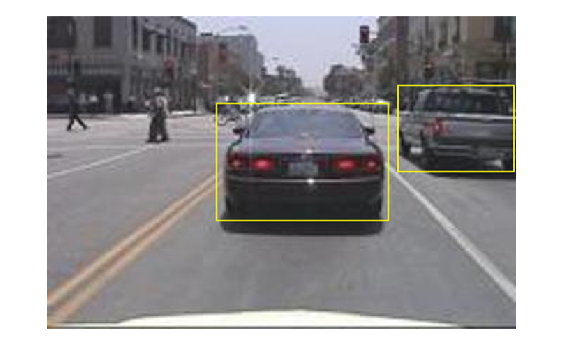

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)